# Plan and Execute Task- and Joint-space Trajectories using ROCR6II Manipulator

This example shows how to generate and simulate interpolated joint trajectories to move from an initial to a desired end-effector pose. The timing of the trajectories is based on an approximate desired end of arm tool (EOAT) speed.

此示例展示了如何生成和模拟内插关节轨迹以从初始姿势移动到所需的末端执行器姿势。 轨迹的定时基于近似期望的手臂工具末端 (EOAT) 速度。

Load the rigid body tree (RBT) ROCR6II model.  载入刚体树模型

clear,clc,close all;
ROCR6II = importrobot('ROCR6II_URDF_File.urdf');
ROCR6II.DataFormat = 'row';
ROCR6II.Gravity = [0, 0, -9.80665];

Set current ROCR6II joint configuration.  设置当前 ROCR6II 关节配置。

currentROCR6IIJConfig = homeConfiguration(ROCR6II);

Get number of joints and the end-effector RBT frame.  获取关节数和末端执行器 RBT 框架

numJoints = numel(currentROCR6IIJConfig);
endEffector = "tool0";

Specify the trajectory time step and approximate desired tool speed.  指定轨迹时间步长和近似所需的工具速度。

timeStep = 0.1; % seconds
toolSpeed = 0.1; % m/s

Set the initial and final end-effector pose.  设置初始和最终末端执行器姿势。

jointInit = currentROCR6IIJConfig;
taskInit = getTransform(ROCR6II,jointInit,endEffector);

taskFinal = trvec2tform([0.3,-0.25,0.05])*troty(pi); %axang2tform([0 1 0 pi]) *rpy2tr([35,-30,90],'deg','xyz')

## Generate Task-Space Trajectory 生成任务空间轨迹

Compute task-space trajectory waypoints via interpolation. 通过插值计算任务空间轨迹航点。

First, compute tool traveling distance. 首先，计算工具移动距离。

distance = norm(tform2trvec(taskInit)-tform2trvec(taskFinal));

Next, define trajectory times based on traveling distance and desired tool speed. 接下来，根据行进距离和所需工具速度定义轨迹时间。

initTime = 0;
finalTime = (distance/toolSpeed) - initTime;
trajTimes = initTime:timeStep:finalTime;
timeInterval = [trajTimes(1); trajTimes(end)];

Interpolate between `taskInit` and `taskFinal` to compute intermediate task-space waypoints. 

在 taskInit 和 taskFinal 之间进行插值以计算中间任务空间航路点

[taskWaypoints,taskVelocities] = transformtraj(taskInit,taskFinal,timeInterval,trajTimes); 

## Control Task-Space Motion 控制任务空间运动

Create a joint space motion model for PD control on the joints. The `taskSpaceMotionModel` object models the motion of a rigid body tree model under task-space proportional-derivative control.

为关节上的 PD 控制创建关节空间运动模型。 taskSpaceMotionModel 对象在任务空间比例微分控制下对刚体树模型的运动进行建模。

tsMotionModel = taskSpaceMotionModel('RigidBodyTree',ROCR6II,'EndEffectorName','tool0');

Set the proportional and derivative gains on orientation to zero, so that controlled behavior just follows the reference positions:

将方向的比例和微分增益设置为零，以便受控行为仅遵循参考位置：

tsMotionModel.Kp(1:3,1:3) = 0;
tsMotionModel.Kd(1:3,1:3) = 0;

Define the initial states (joint positions and velocities).  定义初始状态（关节位置和速度）

q0 = currentROCR6IIJConfig; 
qd0 = zeros(size(q0));

Use ROCR6II to simulate the robot motion. Since reference state changes at each instant, a wrapper function is required to update the interpolated trajectory input to the state derivative at each instant. Therefore, an example helper function is passed as the function handle to the ODE solver. The resultant manipulator states are output in `stateTask`. 

使用 ROCR6II 模拟机器人运动。 由于参考状态在每个时刻都发生变化，因此需要一个包装函数来将内插轨迹输入更新为每个时刻的状态导数。 因此，示例辅助函数作为函数句柄传递给 ODE 求解器。 结果操纵器状态在 stateTask 中输出。

[tTask,stateTask] = ode15s(@(t,state) exampleHelperTimeBasedTaskInputs(tsMotionModel,timeInterval,taskInit,taskFinal,t,state),timeInterval,[q0; qd0]);

## Generate Joint-Space Trajectory 生成关节空间轨迹

Create a inverse kinematics object for the robot. 为机器人创建逆运动学对象

ik = inverseKinematics('RigidBodyTree',ROCR6II);
ik.SolverParameters.AllowRandomRestart = false;
weights = [0.25 0.25 0.25 1 1 1];

Calculate the initial and desired joint configurations using inverse kinematics.  使用逆运动学计算初始和所需的关节配置

initialGuess = wrapToPi(jointInit);
jointFinal = ik(endEffector,taskFinal,weights,initialGuess);
jointFinal = wrapToPi(jointFinal);

Interpolate between them using a cubic polynomial function to generate an array of evenly-spaced joint configurations. Use a B-spline to generate a smooth trajectory.  使用三次多项式函数在它们之间进行插值，以生成一系列均匀分布的关节配置。 使用 B-spline 生成平滑轨迹

ctrlpoints = [jointInit',jointFinal'];   %wrap angle in radians to [-pi pi]
jointConfigArray = cubicpolytraj(ctrlpoints,timeInterval,trajTimes);
jointWaypoints = bsplinepolytraj(jointConfigArray,timeInterval,1);

## Control Joint-Space Trajectory 控制关节空间轨迹

Create a joint space motion model for PD control on the joints. The `jointSpaceMotionModel` object models the motion of a rigid body tree model and uses proportional-derivative control on the specified joint positions.

为关节上的 PD 控制创建关节空间运动模型。 JointSpaceMotionModel 对象对刚体树模型的运动进行建模，并对指定的关节位置使用比例微分控制

jsMotionModel = jointSpaceMotionModel('RigidBodyTree',ROCR6II,'MotionType','PDControl');

Set initial states (joint positions and velocities).  设置初始状态（关节位置和速度）

q0 = currentROCR6IIJConfig; 
qd0 = zeros(size(q0));

Use ROCR6II to simulate the robot motion. Again, an example helper function is used as the function handle input to the ODE solver in order to update the reference inputs at each instant in time. The joint-space states are output in `stateJoint`.

使用 ROCR6II 模拟机器人运动。 同样，示例辅助函数用作 ODE 求解器的函数句柄输入，以便在每个时刻及时更新参考输入。 关节空间状态在 stateJoint 中输出

[tJoint,stateJoint] = ode15s(@(t,state) exampleHelperTimeBasedJointInputs(jsMotionModel,timeInterval,jointConfigArray,t,state),timeInterval,[q0; qd0]);

## Visualize and Compare ROCR6II Trajectories 可视化和比较 ROCR6II 轨迹

Show the initial configuration of the ROCR6II. 显示 ROCR6II 的初始配置

show(ROCR6II,currentROCR6IIJConfig,'PreservePlot',false,'Frames','off');
hold on
axis([-1 1 -1 1 -0.1 1.5]);

Visualize the task-space trajectory. Iterate through the `stateTask` states and interpolate based on the current time.

可视化任务空间轨迹。 遍历 stateTask 状态并根据当前时间进行插值

for i=1:length(trajTimes)
    % Current time 当前时间
    tNow= trajTimes(i);
    % Interpolate simulated joint positions to get configuration at current time 插入模拟关节位置以获取当前时间的配置
    configNow = interp1(tTask,stateTask(:,1:numJoints),tNow);
    poseNow = getTransform(ROCR6II,configNow,endEffector);
    show(ROCR6II,configNow,'PreservePlot',false,'Frames','off');
    plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'b.','MarkerSize',20)
    drawnow;
end

Visualize the joint-space trajectory. Iterate through the `jointTask` states and interpolate based on the current time.

可视化关节空间轨迹。 遍历 JointTask 状态并根据当前时间进行插值

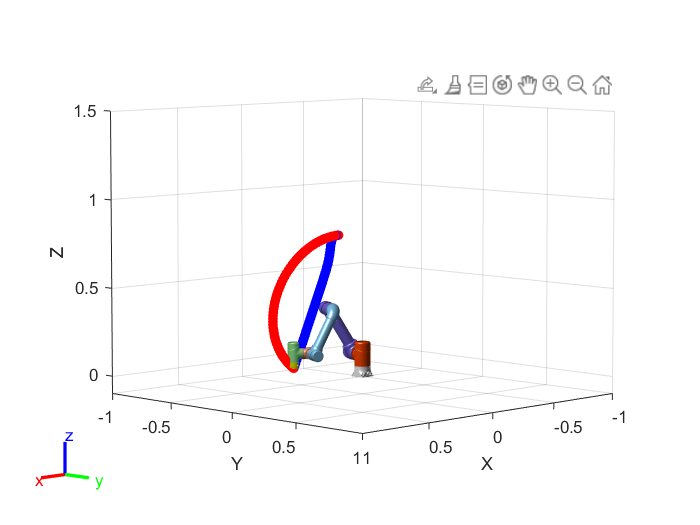

% Return to initial configuration 返回初始配置
show(ROCR6II,currentROCR6IIJConfig,'PreservePlot',false,'Frames','off');

for i=1:length(trajTimes)
    % Current time 
    tNow= trajTimes(i);
    % Interpolate simulated joint positions to get configuration at current time
    configNow = interp1(tJoint,stateJoint(:,1:numJoints),tNow);
    poseNow = getTransform(ROCR6II,configNow,endEffector);
    show(ROCR6II,configNow,'PreservePlot',false,'Frames','off');
    plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'r.','MarkerSize',20)
    drawnow;
end

*Copyright 2021 YUXIN*